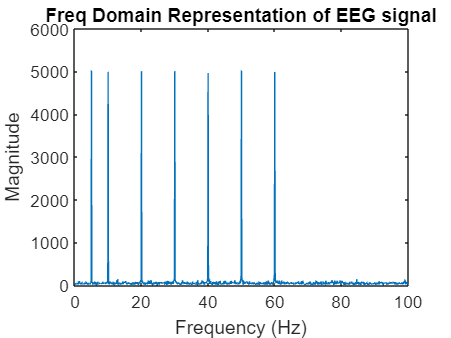

load ('eeg_signal_noisy.mat')

fs = 1000;
t = (0:length(eeg_signal_noisy) - 1) / fs;

% Perform FFT
fft_signal = fft(eeg_signal_noisy);

%Generate the frequency axis

f = (0: length(fft_signal) - 1) * fs / length(fft_signal);

figure;
plot(f, abs(fft_signal));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Freq Domain Representation of EEG signal');

xlim([0, 100]);